# Plot Figure 3

addpath(genpath('../public_code'))
nstrain = 'male_timp';


switch nstrain
    case 'male_timp'
        nstrain_before = 'male_before_timp_180511';
        nstrain_after = 'male_after_timp_180526'; nNodes = 15;
        nstrain_title = 'M1 - male/TIMP';
    case 'male_bsa'
        nstrain_before = ['male_before_bsa_200713']; 
        nstrain_after = 'male_after_bsa_200727'; nNodes = 9 ; %10;
        nstrain_title = 'M4 - male/BSA';
    case 'female_timp'
        nstrain_before = 'female_before_timp_180413';
%         nstrain_after = 'female_after_timp_180430_nomouse13'; 

        nstrain_after = 'female_after_timp_180430'; 
        nNodes = 13; % after removing mouse 13, nNodes becomes 13, was 14
        nstrain_title = 'F1 - female/TIMP';
    otherwise
        error('Wrong strain name. Choose between male_timp, male_bsa, or female_timp.')
end

disp(['nNodes = ' num2str(nNodes)])

nNodes = 15


nEdges = nNodes * (nNodes - 1) / 2;

%
method = 'gd';
[jij2_bf, hir2_bf] = ...
    load_sme_params(nstrain_before, nNodes, method);

[jij2_af, hir2_af] = ...
    load_sme_params(nstrain_after, nNodes, method);


[~, s3_bf] = load_s(nstrain_before, nNodes);
[~, s3_af] = load_s(nstrain_after, nNodes);

## Plot Fig.3B:  Inferred interaction J_{ij} vs. days of experiment, before and after TIMP

%%
[jij_bf, hir_bf] = load_sme_params_full6hr(nstrain_before, nNodes, 'gd');
figure(1)

subplot(2,1,1)
swarmchart(repmat(1:10, nEdges,1), jij_bf,ones(nEdges,10)*36,'k.')
set(gca,'YGrid','on')
ylim([-1.2 1.5])
ylabel('interaction, J_{ij}')
set(gca,'fontsize',12)
xlabel('days of experiment')
xticks(1:10)
xlim([0 11])
box on
title('control')

subplot(2,1,2)
[jij_af, hir_af] = load_sme_params_full6hr(nstrain_after, nNodes, 'gd');
swarmchart(repmat(1:10, nEdges,1), jij_af, ones(nEdges,10)*36,'k.')
set(gca,'YGrid','on')
ylim([-1.2 1.5])
ylabel('interaction, J_{ij}')
set(gca,'fontsize',12)
xlabel('days of experiment')
xticks(1:10)
xlim([0 11])
box on
title('test')

%% Plot Fig. 3D: Inferred food preference Δh_i vs. days of experiment, before and after TIMP

dh_bf = hir2_to_dh2(hir_bf, nNodes);

figure()
subplot(2,1,1)
plot(dh_bf','-','color',[0 0 0]+0.85,'linewidth',0.5)
hold on
plot(dh_bf','k.','markerSize',6)
hold off
xticks(1:10)
xlim([0 11])
ylim([-2 4])
title('control')

xlabel('days of experiment')
ylabel('food preference, \Deltah_i')
set(gca,'fontsize',12)
set(gca,'YGrid','on')


dh_af = hir2_to_dh2(hir_af, nNodes);

subplot(2,1,2)
plot(dh_af','-','color',[0 0 0]+0.85,'linewidth',0.5)
hold on
plot(dh_af','k.','markerSize',6)
hold off
xticks(1:10)
xlim([0 11])
ylim([-2 4])
title('test')

xlabel('days of experiment')
ylabel('food preference, \Deltah_i')
set(gca,'fontsize',12)
set(gca,'YGrid','on')

## Plot Fig. 3C: mean and standard deviation of inferred interaction J_{ij} over 10 days of experiment

%%
figure()
plot_compare_params(jij2_bf, jij2_af, 'J_{ij}')
subplot(2,1,1)
hold on
plot([0 11],[0 0],'color',[0 0 0]+0.8)
plot([0 11],[1 1]*0.05,'color',[0 0 0]+0.8)
plot([0 11],[1 1]*0.1,'color',[0 0 0]+0.8)
hold off
ylim([-0.02 0.12])
legend('ctrl','test')

subplot(2,1,2)
hold on
plot([0 11],[1 1]*0.2,'color',[0 0 0]+0.8)
plot([0 11],[1 1]*0.3,'color',[0 0 0]+0.8)
hold off
ylim([0.15 0.35])

## Plot Fig. 3E: mean and standard deviation of food preference over 10 days of experiments, before and after TIMP.


dh2_bf = hir2_to_dh2(hir2_bf, nNodes);
dh2_af = hir2_to_dh2(hir2_af, nNodes);


figure()
plot_compare_params(dh2_bf, dh2_af, '\Deltah_i')
subplot(2,1,1)
hold on
plot([0 11],[0 0],'color',[0 0 0]+0.8)
plot([0 11],[1 1],'color',[0 0 0]+0.8)
plot([0 11],[1 1]*2,'color',[0 0 0]+0.8)
hold off
ylim([-0.5 2.4])
legend('ctrl','test')

subplot(2,1,2)
hold on
plot([0 11],[1 1]*0.5,'color',[0 0 0]+0.8)
plot([0 11],[1 1],'color',[0 0 0]+0.8)
plot([0 11],[1 1]*1.5,'color',[0 0 0]+0.8)
hold off
ylim([0.3 1.6])

## Fig. 3F Plot log likelihood

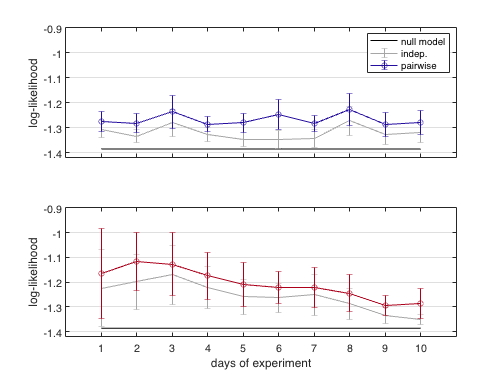

%%
[jij2_bf, hir2_bf] = load_sme_params_full6hr(nstrain_before, nNodes, 'gd');
llh3_bf = compute_loglikelihood_10days(jij2_bf, hir2_bf, s3_bf);

%
[jij2_af, hir2_af] = load_sme_params_full6hr(nstrain_after, nNodes, 'gd');
llh3_af = compute_loglikelihood_10days(jij2_af, hir2_af, s3_af);
figure()
subplot(2,1,1)
plot(squeeze(mean(llh3_bf(1,:,:),2)),'k-')
hold on
errorbar(squeeze(mean(llh3_bf(2,:,:),2)), ...
    squeeze(std(llh3_bf(2,:,:),0,2)), ...
    'color',[0 0 0]+0.65)
errorbar(squeeze(mean(llh3_bf(3,:,:),2)), ...
    squeeze(std(llh3_bf(3,:,:),0,2)), ...
    '-o', 'color',[36 14 159]/255) 
hold off
xlim([0 11])
xticks(1:10)
xticklabels('')
ylim([-1.42 -0.9])
set(gca,'fontsize',12)
ylabel('log-likelihood')
set(gca,'YGrid','on')
legend('null model','indep.','pairwise')

subplot(2,1,2)
plot(squeeze(mean(llh3_af(1,:,:),2)),'k-')
hold on
errorbar(squeeze(mean(llh3_af(2,:,:),2)), ...
    squeeze(std(llh3_af(2,:,:),0,2)), ...
    'color',[0 0 0]+0.65)
errorbar(squeeze(mean(llh3_af(3,:,:),2)),...
    squeeze(std(llh3_af(3,:,:),0,2)),...
    '-o','color',[172 0 27]/255)
hold off
set(gca,'YGrid','on')
xlim([0 11])
xticks(1:10)
ylim([-1.42 -0.9])
set(gca,'fontsize',12)
xlabel('days of experiment')
ylabel('log-likelihood')

function plot_compare_params(params1, params2, params_name)

%%
mean_params1 = squeeze(nanmean(params1));
std_params1 = squeeze(nanstd(params1));
mean_params2 = squeeze(nanmean(params2));
std_params2 = squeeze(nanstd(params2));


subplot(2,1,1)
errorbar(1:10, nanmean(mean_params1,2),...
    nanstd(mean_params1,0,2)/sqrt(2),'-','marker','.','markerSize',12) %,...
    %'color',[24 0 249]/255)
hold on
errorbar(1:10, nanmean(mean_params2,2),...
    nanstd(mean_params2,0,2)/sqrt(2),'-','marker','*','markerSize',12) %, ...
    %'color',[255 171 46]/255)
hold off
xlabel('day of experiment')
ylabel(['\langle' params_name '\rangle'])
% ylabel('Food preference, \Deltah_{ir}')
% legend('before','after')
set(gca,'fontsize',12)
xlim([0 11])

subplot(2,1,2)
errorbar(1:10, nanmean(std_params1,2),...
    nanstd(std_params1,0,2)/sqrt(2),'-','marker','.','markerSize',12) %,...
    %'color',[24 0 249]/255)
hold on
errorbar(1:10, nanmean(std_params2,2),...
    nanstd(std_params2,0,2)/sqrt(2),'-','marker','*','markerSize',12) %, ...
    %'color',[255 171 46]/255)
hold off
xlabel('day of experiment')
% ylabel('\sigma_{param}')
ylabel(['\sigma_{' params_name '}'])
% ylabel('Food preference, \Deltah_{ir}')
% legend('before','after')
set(gca,'fontsize',12)
xlim([0 11])

end



function [dh] = hir_to_dh(hir, nNodes, nStates)

hmat = reshape(hir, nNodes, nStates-1); 
dh = hmat(:,2) - hmat(:,1) - hmat(:,3);

end

function [dh2] = hir2_to_dh2(hir2, nNodes)

nStates = 4;
[~, nDays, nbs] = size(hir2);

dh2 = nan(nNodes, nDays, nbs);
for iday = 1:nDays
    for ibs = 1:nbs
        dh2(:, iday, ibs) = hir_to_dh(hir2(:, iday, ibs), nNodes, nStates);
    end
end


end

function [s2, s3] = load_s(nstrain, nNodes)

nDays = 10;
s3 = zeros(nNodes, 21600/2, nDays);
s2 = [];
%
for dayId = 0:nDays-1

    fn = ['etho_' nstrain '_12hr_dt2s_d' num2str(dayId) '.mat'];

    load(fn,'s');
    s = s';
    s = int64(s);

    %%
    if strcmp(nstrain, 'male_before_bsa_200713')
%         s = s([1:2 4:10 12],:); % no dead. For male before BSA only
        s = s([1:2 4:8 10 12],:); % nim
%         s = s([1 4:8 10 12],:); % nim2
    end

    if strcmp(nstrain, 'male_after_bsa_200727')
            s = s([1:7 9:10],:); % nim
%             s = s([1 3:7 9:10],:);  % nim2
    end

    if strcmp(nstrain, 'female_before_timp_180413')
        s = s([1:12 14],:); % For female, exclude mouse # 13
    end

    if strcmp(nstrain, 'female_after_timp_180430')
        s = s([1:12 14],:); % For female, exclude mouse # 13
    end

    %%
    s = remove_tunnel(s);

    %%
    s = s(:,1801:1800*7);
%     s = s(:,1:3600*3);

    s3(:, :, dayId+1) = s;
    
    s2 = [s2 s];
end



end

function [jij2, hir2] = load_sme_params_full6hr(nstrain, nNodes, method)

%%
nStates = 4;

tp = '~/MyDocuments/biophysics/projects/social_mice/output/';

nDays = 10;
jij2 = nan(nNodes*(nNodes-1)/2, nDays);
hir2 = nan(nNodes*(nStates-1), nDays);


for dayId = 0:nDays-1
    if strcmp(nstrain, 'female_before_timp_180413') || ...
        strcmp(nstrain, 'female_after_timp_180430') || ...
        strcmp(nstrain, 'male_before_bsa_200713') || ...
        strcmp(nstrain, 'male_after_bsa_200727') 
        fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' ...
            nstrain '_nim_iday' num2str(dayId+1) '_full6hr.mat']; 
        % nim = no inactive mice
%             fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' ...
%                 nstrain '_iday' num2str(dayId+1) ...
%                 '_ibs' num2str(ibs) '.mat'];
    else
        fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' ...
            nstrain '_iday' num2str(dayId+1) '_full6hr.mat'];
    end


    switch method
        case 'gd'
            load(fp, 'jij_gd_eachday', 'hir_gd_eachday');
            jij2(:, dayId+1) = jij_gd_eachday;
            hir2(:, dayId+1) = hir_gd_eachday;
        case 'l1'
            load(fp, 'jij_l1_eachday', 'hir_l1_eachday');
            jij2(:, dayId+1) = jij_l1_eachday;
            hir2(:, dayId+1) = hir_l1_eachday;
    end
end

end

function [jij2, hir2] = load_sme_params(nstrain, nNodes, method)

%%
nStates = 4;

tp = '~/MyDocuments/biophysics/projects/social_mice/output/';

nbs = 10;
nDays = 10;
jij2 = nan(nNodes*(nNodes-1)/2, nDays, nbs);
hir2 = nan(nNodes*(nStates-1), nDays, nbs);


for dayId = 0:nDays-1
    for ibs = 1:nbs
        if strcmp(nstrain, 'female_before_timp_180413') || ...
            strcmp(nstrain, 'female_after_timp_180430') || ...
            strcmp(nstrain, 'male_before_bsa_200713') || ...
            strcmp(nstrain, 'male_after_bsa_200727') 
            fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' ...
                nstrain '_nim_iday' num2str(dayId+1) ...
                '_ibs' num2str(ibs) '.mat']; % nim = no inactive mice
%             fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' ...
%                 nstrain '_iday' num2str(dayId+1) ...
%                 '_ibs' num2str(ibs) '.mat'];
        else
            fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' ...
                nstrain '_iday' num2str(dayId+1) ...
                '_ibs' num2str(ibs) '.mat'];
        end


        switch method
            case 'gd'
                load(fp, 'jij_gd_eachday', 'hir_gd_eachday');
                jij2(:, dayId+1, ibs) = jij_gd_eachday;
                hir2(:, dayId+1, ibs) = hir_gd_eachday;
            case 'l1'
                load(fp, 'jij_l1_eachday', 'hir_l1_eachday');
                jij2(:, dayId+1, ibs) = jij_l1_eachday;
                hir2(:, dayId+1, ibs) = hir_l1_eachday;
        end
    end
end

end





%%

function [llh3] = compute_loglikelihood_10days(jij2, hir2, s3)

[nNodes, nSamples, nDays] = size(s3);

llh3 = zeros(3, nNodes, nDays);
for iday = 1:nDays
    iday = iday;
    s = s3(:,:,iday);
    llh2 = compute_loglikelihood(jij2(:,iday), hir2(:,iday), s);
    llh3(:,:,iday) = llh2;
end


end

function [llh2] = compute_loglikelihood(jij, hir, s)

[nNodes, nSamples] = size(s);
nStates = 4;

llh2 = zeros(3, nNodes);
    
jijMat = recoverUpt(jij, nNodes);
hirMat = reshape(hir, nNodes, nStates-1);
hirMat = [hirMat zeros(nNodes,1)];


for imice = 1:nNodes
%%
    llh_null = log(1/nStates); 
    llh2(1, imice) = llh_null;

    m = mean(s(imice,:) == (1:nStates)',2);
    llh_indep = sum (log(m) .* m);
    llh2(2, imice) = llh_indep;
    
    % compute_local_energy1.

    
    llh_pw = 0; 
    for t = 1:nSamples
        mys = s(:, t);
        localE = compute_local_energy1(mys, imice, jijMat, hirMat);
        
        localE2 = zeros(1, nStates);
        mys_temp = mys;
        for istate = 1:nStates
            mys_temp(imice) = istate;
            localE2(istate) = compute_local_energy1(mys_temp, imice, jijMat, hirMat);
        end
        lh = exp(-localE) / sum(exp(-localE2));
        llh_pw = llh_pw + log(lh);
    end
    llh_pw = llh_pw / nSamples;
    llh2(3, imice) = llh_pw;
end


end